clear ; close all
sigma_a=3;
sigma_w=5*pi/180;
N=1e3;
wk=randn(1,N)*sigma_w;
ak=randn(1,N)*sigma_a;
figure ; subplot 121
plot(wk,ak,'.');axis square
title(" Gaussian random turnrate & acceleration",'fontsize',12,'fontweight','bold');
xlabel("acceleration m/s^2 ",'fontsize',12,'fontweight','bold');
ylabel("turnrate deg/s",'fontsize',12,'fontweight','bold');
xini=0;yini=0;
T=3;
vk=300;
phd=(1-2*rand)*pi;
%  phd=pi/4;
xd=xini+(vk+T*ak)./wk.*sin(phd+T.*wk)-vk./wk.*sin(phd)...
    +ak./(wk.^2).*(cos(phd+T*wk)-cos(phd));
  yd=yini-(vk+T*ak)./wk.*(cos(phd+T*wk)-cos(phd))...
      +(ak/wk.^2).*(sin(phd+T*wk)-sin(phd));
%  yd=yini-(vk+T*ak)./wk.*cos(phd+T*wk)+vk./wk.^2.*cos(phd)...
%      +(ak/wk.^2).*(sin(phd+T*wk)-sin(phd));
%
subplot 122; plot(xd,yd,'.');axis square;grid on
xlabel("x cordinates of robot",'fontsize',12,'fontweight','bold');
ylabel("y coordinates of robot",'fontsize',12,'fontweight','bold');
title(['\phi_k = ' num2str(phd*180/pi) ' deg.'])
xmin=min(xd); ymin=min(yd); allmin = min([xmin ymin]);
xmax=max(xd); ymax=max(yd); allmax = max([xmax ymax]);
all=mean(sqrt(xd.^2+yd.^2));
h=line([0 all*cos(phd)], [0 all*sin(phd)])

h =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 -134.9432]
              YData: [0 886.4084]
              ZData: [1×0 double]

  Show all properties


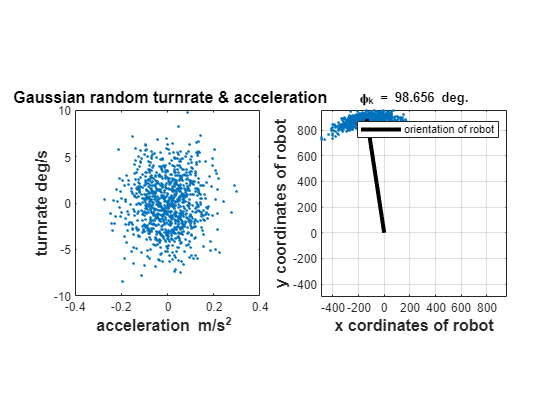

legend(h,"orientation of robot")
set(h,'linewidth',3,'color','k')
ylim([allmin allmax]); xlim([allmin allmax])

disp(['\phi_k = ' num2str(phd*180/pi) ' deg.'])

\phi_k = 98.656 deg.
